GBM8770 - Projet Automne 2019

# Multi-Scale Line Detector

Patenaude Valérie 1896917

Kedzierski-Tanguay Christophe 1827066

## Partie I: Implémentation de la MSLD

#### Préparatifs

**Q1.** La valeur du masque est : 

W = 15;
L = (1:2:W);
n_orientation = 12; 
msld = MSLD(W,L,n_orientation);    

msld.avg_mask

ans =     0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.00

voir TODO Q1 dans MSLD

**Q2. **

Le masque moyenneur est construit en divisant une matrice de taille WxW par la somme de ses composantes. Pour le masque qui permet de détecter les lignes, on débute avec une matrice de taille LxL qui contient une ligne de 1 au milieu. On fait tourner cette matrice et on la stocke dans l'objet Line Detector pour les 12 orientations souhaitées. On obtient donc une matrice de taille L x L x nb orientations.

Voir TODO Q2 dans MSLD

**Q3.** 

type load_dataset.m


function [train, test] = load_dataset()
    % Charge les images de l'ensemble d'entrainement et de test dans 2
    % objets struct. Pour chaque échantillon, il faut créer une ligne dans
    % le dataset contenant les attributs ['line', 'data', 'label', 'mask'].
    % On pourra ainsi accéder à la première image du dataset d'entrainement
    % avec train(1).data.
    % La copie intégrale d'un dataset peut se faire avec la commande: 
    %       trainCopie = train(1,:);
    
    files_test = dir('DRIVE/data/test/*.png');
    files_train = dir('DRIVE/data/training/*.png');
    
    train = struct(['name' 'data' 'label' 'mask'], []);
    test = struct(['name' 'data' 'label' 'mask'], []);
    
    for i=1:length(files_train)
        name = files_train(i).name;
        train(i).name = name;
        %%% TODO I.Q3 Chargez les images data, label et mask:
        train(i).data = im2double(imread(['DRIVE/data/training/',name])); % Type: double, intensité comprises entre 0 et 1);
        train(i).

[train, test] = load_dataset()

train = 1×20 struct array with fields:
    namedatalabelmask
    name
    data
    label
    mask


test = 1×20 struct array with fields:
    namedatalabelmask
    name
    data
    label
    mask


I1 = train(1)

I1 = struct with fields:
    namedatalabelmask: []
                 name: '21.png'
                 data: [584×565×3 double]
                label: [584×565 logical]
                 mask: [584×565 logical]


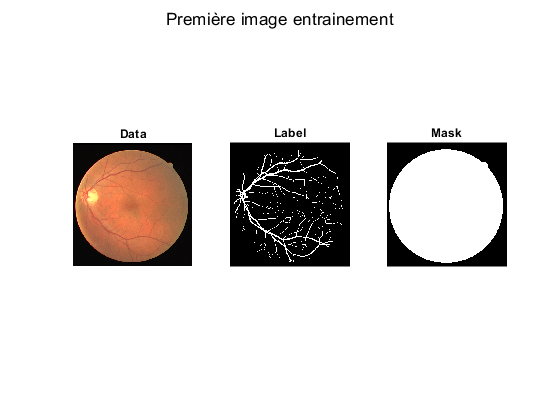

figure(), subplot(1, 3, 1);
imshow(I1.data, [])
title('Data')
subplot(1, 3, 2)
imshow(I1.label, [])
title('Label')
subplot(1, 3, 3)
imshow(I1.mask, [])
title('Mask')
sgtitle('Première image entrainement')

#### Basic Line Detector

**Q4.** 

Voir TODO Q4 dans MSLD

**Q5.** 

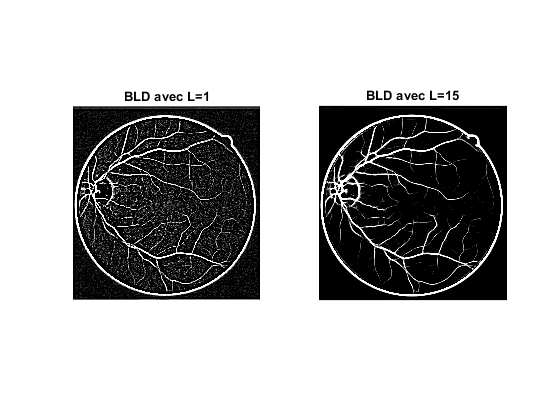

grey_lvl = 1-I1.data(:,:,2);
L = 1;
R_L1 = basicLineDetector(msld,grey_lvl,L);

L = 15;
R_L15 = basicLineDetector(msld,grey_lvl,L);

figure(), subplot(1, 2, 1);
imshow(R_L1)
title('BLD avec L=1')
subplot(1, 2, 2)
imshow(R_L15)
title('BLD avec L=15')

On constate que le BLD avec L=1 permet de mieux détecter les petits vaisseaux et les croisements. Toutefois, l'image BLD avec L=1 contient beaucoup plus de bruit que l'image BLD avec L=15. On peut expliquer cela par le fait qu'avec des petites lignes on reste dans un voisinage plus petit, donc on a moins l'influence des pixels autours, ce qui permet de détecter les plus petits détails alors qu'avec L=15 on considère davantage l'environnement.

#### **Multi-Scale Line Detector**

**Q6.** 

Voir TODO Q6 dans MSLD

**Q7. **

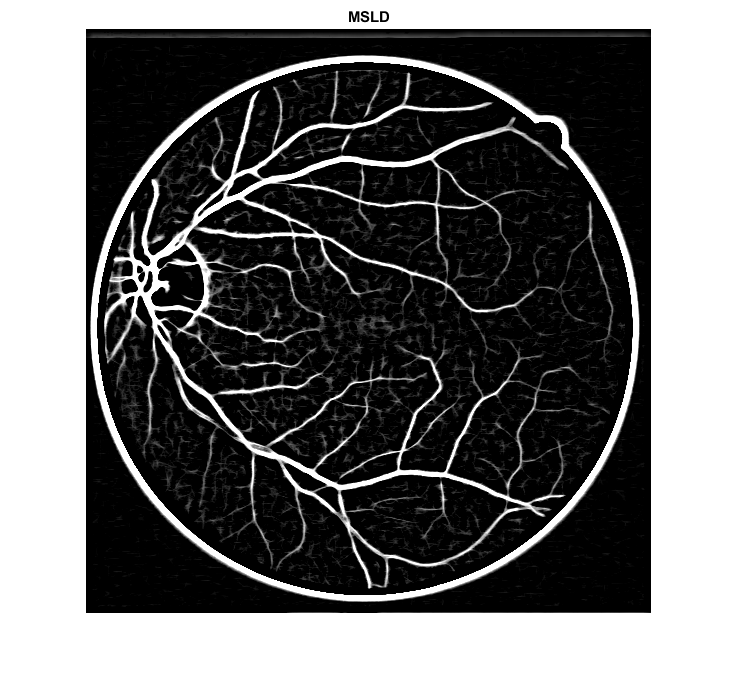

Rcombined = multiScaleLineDetector(msld, I1);
figure(),
imshow(Rcombined);
title('MSLD')

En comparant les images obtenues à la suite de l'exécution du MSLD, il est possible d'observer que les petits vaisseaux sanguins sont plus facilement distingables dans l'image du MSLD que dans le BLD. De plus, les croisements des vaisseaux sont également mieux définis. Étant donné que le MSLD est en réalité un BLD avec des lignes de longueurs variables, les avantages des petites et grandes longueurs sont exploitées. En effet, le bruit de fond est diminué grâce au grand L et les petits vaisseaux sont plus visibles grâce au petit L. 

#### Apprentissage du seuil

**Q8.**

acc = (P*TPR+N*(1-TNR)/(S)

**Q9.**

Voir TODO Q9 dans MSLD

**Q10.**

Voir TODO Q10. dans MSLD

**Q11.**

[threshold, accuracy, msld] = msld.learnThreshold(train);
threshold

threshold = 0.5702

accuracy

accuracy = 0.9249

La raison pour laquelle il est essentiel de conserver une partie des images lors de l'entraînement est de ne pas biaiser l'apprentissage du seuil. De fait, lorsque que nous utilisons la méthode ROC pour calculer le seuil, l'apprentissage est effectué sur l'ensemble de données d'entraînement et nous obtenons un seuil X. Afin de valider l'exactitude du seuil, il est essentiel de le valider avec un ensemble de données différent qui n'a pas été utilisé dans l'apprentissage. Cet ensemble de données permet donc de vérifier que l'apprentissage n'est pas biaisé et produit donc un résultat de seuil valide.

**Q12.**

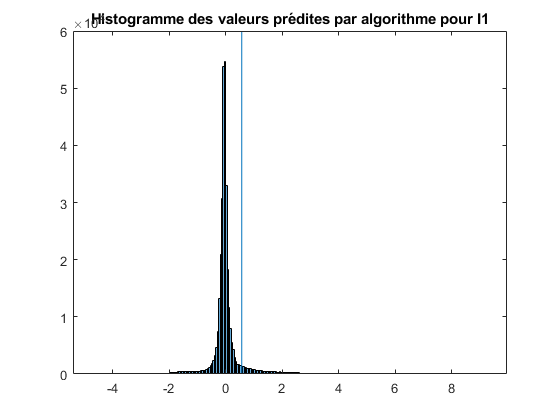

figure(),
histogram(Rcombined)
hold on
y = line([threshold threshold], ylim);
x = linspace(0,8,100);
plot(x,y)
title('Histogramme des valeurs prédites par algorithme pour I1')
hold off

Un seuillage d'Otsu ne serait pas utilisable de manière efficace pour identifier un tel seuil, car la valeur de seuil obtenue ne sépare par les valeurs d'intensité de manière à former une «vallée» entres les classes (vaisseaux et fond), comme on peut observer sur l'histogramme.

#### **Affichage et région d'intérêt**

**Q13.**

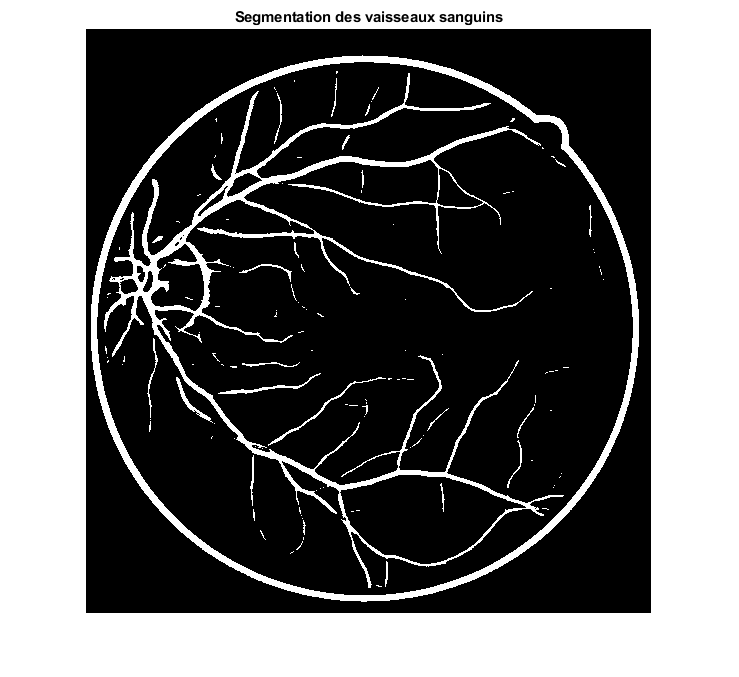

vessels = msld.segmentVessels(I1);
figure(),
imshow(vessels)
title('Segmentation des vaisseaux sanguins')

**Q14.**

Les erreurs de segmentation aux bords du fond de l'oeil sont le résultat de la segmentation de la ligne de contour de l'oeil. Cette dernière a été introduite dans l'image lors de l'application du MSLD, car la ligne de l'oeil possède une intensité élevée et est donc interprétée par le MSLD comme étant un vaisseau sanguin.

**Q15.**

disk = strel('disk',6);

disk = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


for i = 1:length(train)
    train(i).mask = imerode(train(i).mask,disk);
end
[threshold, accuracy, msld] = msld.learnThreshold(train);
threshold

threshold = 0.5702

accuracy

accuracy = 0.9344

I1_new = train(1);

I1_new = struct with fields:
    namedatalabelmask: []
                 name: '21.png'
                 data: [584×565×3 double]
                label: [584×565 logical]
                 mask: [584×565 logical]


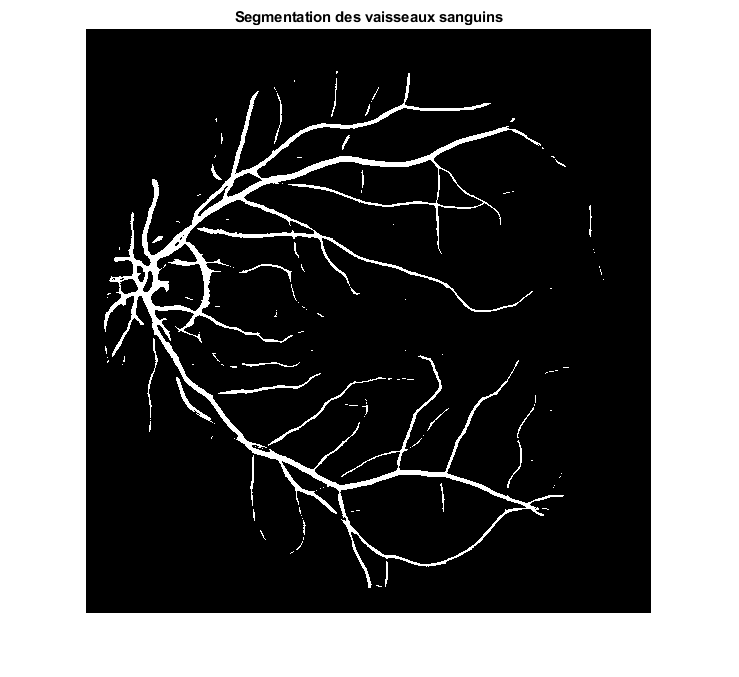

vessels = msld.segmentVessels(I1_new);
figure(),
imshow(vessels.*train(1).mask)
title('Segmentation des vaisseaux sanguins')

On constate que la valeur de threshold reste la même, soit 0,5702. La précision est toutefois améliorée. Elle passe de 0,9249 à 0,9344. Cela s'explique par le fait que la région érodée qui contenait plusieurs faux-positifs a été enlevée pour toute les images, donc la précision est augmentée pour tous les thresholds. Alors la meilleure précision est obtenue avec le même threshold pour les deux masques. 

**Q16.**

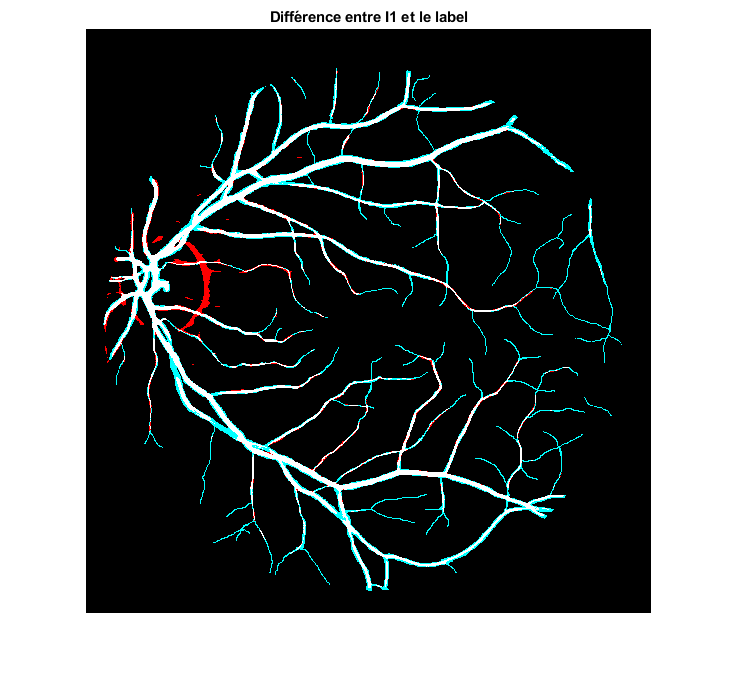

msld.showDiff(I1_new)
title('Différence entre I1 et le label')

## Partie II : Métriques de segmentation

#### Précision Globale et Locale

**Q1.**

[accuracy, confusion_matrix] = msld.naiveMetrics(train)

accuracy = 0.9344

confusion_matrix =      3710322       81456
      204016      356005


accuracy = 0.9344

confusion_matrix =      3710322       81456
      204016      356005


**Q2.**

Les auteurs proposent d'utiliser la précision locale parce que la précision globale a tendance à être très élevée puisque les pixels de fond occupent environ 80% de l'image et sont majoritairement identifiés correctement. Il est donc difficile de comparer la précision de différentes méthodes. La précision locale permet donc d'obtenir une valeur plus juste de la précision de l'algorithme, puisqu'elle utilise seulement les pixels près des vaisseaux. 

**Q3.**

disk = strel('disk',6); %size = 3 dans l'article donc 6 pour un disque?

disk = strel is a disk shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


test2 = test;
for i = 1:length(train)
    test2(i).mask = imdilate(test2(i).label,disk);
end
[local_accuracy, confusion_matrix] = msld.naiveMetrics(test2)

local_accuracy = 0.8776

confusion_matrix =      1773939       76732
      220428      357517


local_accuracy = 0.8776

confusion_matrix =      1773939       76732
      220428      357517


**Q4.**

On peut voir sur l'image de la question I.16 que les petits vaisseaux sont tous apparus comme étant faux-négatif, donc l'algorithme ne les a pas détectés alors qu'il aurait du. Puisque ces vaisseaux sont très petits, ils représentent peu de pixels sur l'image totale, donc ils n'ont pas vraiment d'influence sur la précision globale. Cependant, en utilisant seulement l'espace autour des vaisseaux ils ont un plus grand impact, alors on peut plus facilement juger de la qualité de la détection des petits vaisseaux de l'algorithme.

#### Indice Dice

**Q5.**

L'indice Dice permet de mesurer la similarité de deux échantillons. Il répond aux limitations de la précision globale parce qu'il ne prend pas en compte les vrais négatifs qui correspondent à tous les pixels de fond donc il ne va pas donner de résultats élevés seulement à cause du fond.

**Q6.**

[diceIndex] = msld.dice(test)

diceIndex = 0.6891

diceIndex

diceIndex = 0.6891

#### Courbe ROC et aire sous la courbe

**Q7.**

0 : il y a seulement des faux-positifs

0,5 : il y a autant de faux-positifs que de vrai-positifs

1 : il y a seulement des vrais positifs

**Q8.**

figure(), subplot(1, 2, 1)
[aur_global] = msld.plotROC(test)

aur_global = 0.9061

title('Aire sous la courbe de la région globale')
subplot(1, 2, 2)
[aur_local] = msld.plotROC(test2)

aur_local = 0.8982

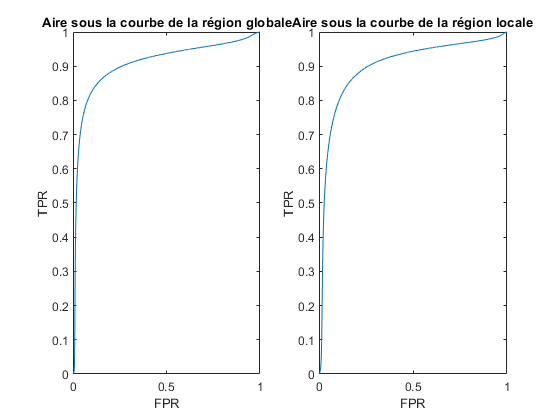

title('Aire sous la courbe de la région locale')

L'AUR pour la région d'intérêt globale est de 0,9061, ce qui est plus grand que l'AUR pour la région locale de 0,8982. Cela est dû au fait que la région globale utilise les pixels du fond de l'image, il y a donc plus de vrais positifs que dans la région locale. 

## Partie III : Discussion

Points forts :

- Bonne détection des principaux vaisseaux

- Peu de faux positifs, ce qui signifie que les pixels détectés comme étant des vaisseaux sanguins le sont vraiment.

- Bonne précision, la précision obtenue est semblable à celle de l'article soit 0,9344 pour la précision globale et 0,8982 pour la précision locale. La précision locale obtenue est meilleure que celle de l'article qui est de 0,7883.

Points faibles:

- Beaucoup de faux-négatifs, donc les petits vaisseaux ne sont pas bien détectés.

- Notre algorithme est lent à s'exécuter. Le fait que Matlab n'est pas un langage conçu pour les boucles, (tel qu'appris dans le cours de CSI), contribue certainement au ralentissement de la méthode.

- Peu de données pour l'entrainement, donc le modèle n'est pas très généralisé.

**Q1. **

W = 15 parce que le diamètre des gros vaisseaux est généralement de 7 à 8 pixels, donc le vaisseau peut être entièrement compris dans le filtre

L = 1 à 15 parce que les petites valeurs permettent de détecter les petits détails et les grandes valeurs permettent de réduire le bruit. On ne dépasse pas 15 afin de rester dans la fenêtre du filtre moyenneur. 

n_orientation = 12  

## Partie IV : Validation des hypothèses de l'article

Les auteurs de l'article ont soulevés plusieurs problèmes reliés aux méthodes déjà existantes. C'est porblèmes consistent majoritairement à une mauvaise segmentation des vaisseaux lorsque les pixels de reflets central dans ces derniers ne sont pas associés ensemble, la fusion de deux vaisseaux près l'un de l'autre et une difficulté à faire le suivi des vaisseaux après que ceux-ci se soient croisés.

À la suite de l'implémentation de l'algorithme de l'article, nos observation des résultats nous permettent de confirmer que cette méthode ne fusionne pas les vaisseaux sanguins qui sont près l'un de l'autre. En effet, l'analyse de l'image colorée de la segmentation contient très peu de pixels rouges (faux-positifs) dans les régions où les vaisseaux sanguins étaient très près les uns des autres, ce qui prouve que l'algorithme est efficace pour cet aspect.

De plus, comme pour la fusion des vaisseaux, l'algorithme résoud le problème associé à leur séparation lorsqu'ils présentent une bande de lumière centrale de grande intensité. De fait, en observant l'image colorée de la segmentation, aucun vaisseau ne contient une bande de pixels bleus (faux négatifs) représentant la séparation de ce dernier en son centre.

Toutefois, la méthode proposée par les auteurs ne permet pas de détecter efficacement les croisements des vaisseaux sanguins. En effet, aucun croisement n'est détecté dans l'image colorée de la segmentation. Il y a également une forte concentration de faux-négatifs dans ces zones, démontrant ainsi l'inefficatité de l'algorithme à résoudre ce problème. 

Finalement, les petits vaisseaux sanguins sont difficilement identifiés par le MSLD. En effet, l'image colorée de la segmentation nous montre que la grande majorité des faux-négatifs est en fait des petits vaisseaux qui n'ont pas été détectés. 

Afin d'améliorer les résultats obtenus avec la méthode proposée, nous pourrions utiliser le BLD avec une petite valeur de L afin de détecter les petits vaisseaux sanguins efficacement. Par la suite, tout en faisant augmenter la valeur de L progressivement, il serait intéressant de superposer les images et de les recaler afin de conserver tous les détails. Par contre, cela signifierait que nous conserverions également le bruit de chacune des images. Afin de contrer cette problématique, l'application de filtres supplémentaires sur l'image d'origine dans le but de réduire le bruit serait très pertinente. 